**Mini quiz -- Linearization template**

**Data**

x = [0    0.2    0.4    0.6    0.8    1.0    1.2    1.4    1.6    1.8    2.0]

x =          0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000



y = [0.5    0.7    0.7    0.6    0.9    0.8    1.3    1.6    1.9    2.3    2.4]

y =     0.5000    0.7000    0.7000    0.6000    0.9000    0.8000    1.3000    1.6000    1.9000    2.3000    2.4000


**Plot data**

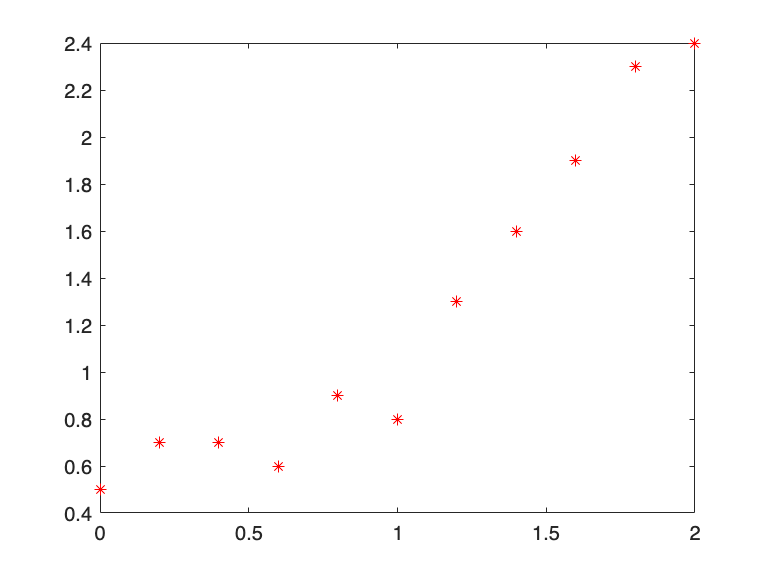

plot(x, y, 'r*')

**Transform data**

new_x = x

new_x =          0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000


new_y = log(y)

new_y =    -0.6931   -0.3567   -0.3567   -0.5108   -0.1054   -0.2231    0.2624    0.4700    0.6419    0.8329    0.8755


**Perform linear regression & plot dataset + fitted line**

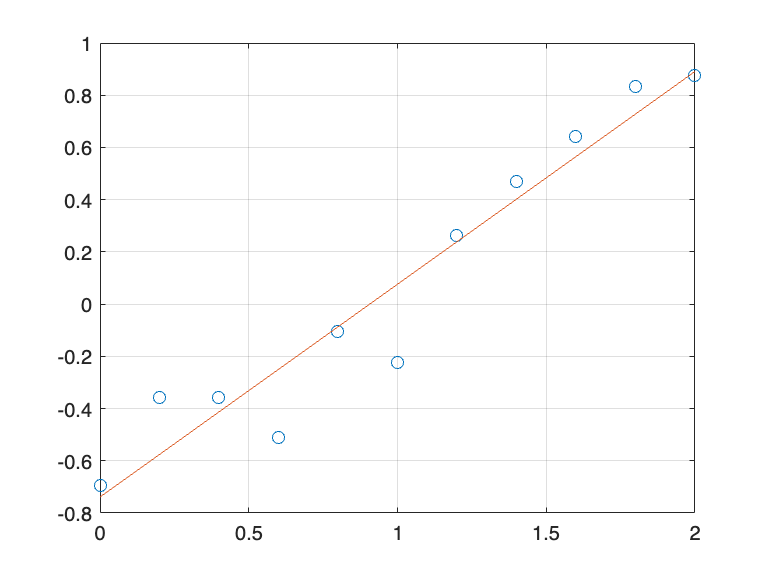

a =     0.8148   -0.7388


r2 = 0.9260

[a, r2] = linregr(new_x, new_y)


my_slope = a(1)

my_slope = 0.8148

my_intercept = a(2)

my_intercept = -0.7388

**Computer parameters of nonlinear equation from the fitted line**

alpha = exp(my_intercept)

alpha = 0.4777

beta = my_slope

beta = 0.8148

**Plot the original data with the best fit nonlinear curve**

xp = linspace(min(x), max(x), 100)

xp =          0    0.0202    0.0404    0.0606    0.0808    0.1010    0.1212    0.1414    0.1616    0.1818    0.2020    0.2222    0.2424    0.2626    0.2828    0.3030    0.3232    0.3434    0.3636    0.3838    0.4040    0.4242    0.4444    0.4646    0.4848    0.5051    0.5253    0.5455    0.5657    0.5859    0.6061    0.6263    0.6465    0.6667    0.6869    0.7071    0.7273    0.7475    0.7677    0.7879    0.8081    0.8283    0.8485    0.8687    0.8889    0.9091    0.9293    0.9495    0.9697    0.9899


yp = alpha .* exp(beta .* xp)

yp =     0.4777    0.4856    0.4937    0.5019    0.5102    0.5187    0.5273    0.5360    0.5449    0.5540    0.5632    0.5725    0.5820    0.5917    0.6015    0.6115    0.6216    0.6320    0.6425    0.6531    0.6640    0.6750    0.6862    0.6976    0.7091    0.7209    0.7329    0.7450    0.7574    0.7700    0.7828    0.7958    0.8090    0.8224    0.8360    0.8499    0.8640    0.8784    0.8929    0.9078    0.9228    0.9381    0.9537    0.9695    0.9856    1.0020    1.0186    1.0355    1.0527    1.0702


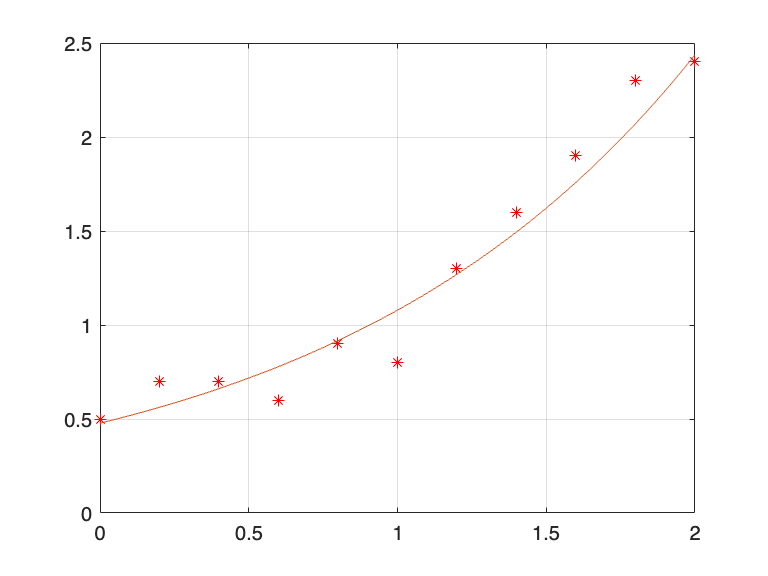


plot(x, y, 'r*', xp, yp)
grid on

**Predict the value of y for the given x**

xtest = 1.1

xtest = 1.1000

ytest = alpha .* exp(beta .* xtest)

ytest = 1.1706